# Uvp6 Characterisation of sensibility

Picheral 2018/05/26

clear all
close all
clc
scrsz = get(0,'ScreenSize');
warning('OFF');

## Settings

segmentation = 50;
angle_limit = 2;
pixel_ve = 0.073;
pixel_ho = 0.095;
pixel = 0;

% Get operator name
operator = input('Enter operator first and last name (default : Alice Pierret)','s');
if isempty(operator); operator = 'Alice Pierret'; end

% Fill in Instrument serial number
uvp_cam = input('Input UVP CAMERA serial number (xxxxxxxx) ','s');
uvp_light = input('Input UVP LIGHT serial number (xxxxxxx) ','s');

% Select type of light to define FOV
while (pixel == 0)
%     uvp_light_type = input('Input UVP LIGHT type (Ve/Ho)(default : Ve) ','s');
%     if isempty(uvp_light_type); uvp_light_type = 'Ve';end
    uvp_light_type = 'Ve';
    if strcmp(uvp_light_type,'Ve')
        pixel = pixel_ve;
        area = .151 * .1805;
    elseif strcmp(uvp_light_type,'Ho')
        pixel = pixel_ho;
    else
        disp("Unkown UVP LIGHT type")
    end
end

% Select VE type for shutter computing
if strcmp(uvp_light_type, 'Ve')
    ve_light_type = input('Input VE LIGHT type (Ve/Ve+)(default : Ve+)', 's');
    if isempty(ve_light_type); ve_light_type = 'Ve+';end
    if strcmp(ve_light_type,'Ve')
        goal_shutter = 300;
        shutter_factor = 49.8811;
    elseif strcmp(ve_light_type, 'Ve+')
        goal_shutter = 80;
        shutter_factor = 47.6592;
    else
        disp("Unkown Ve light type")
    end
end

## Select source images

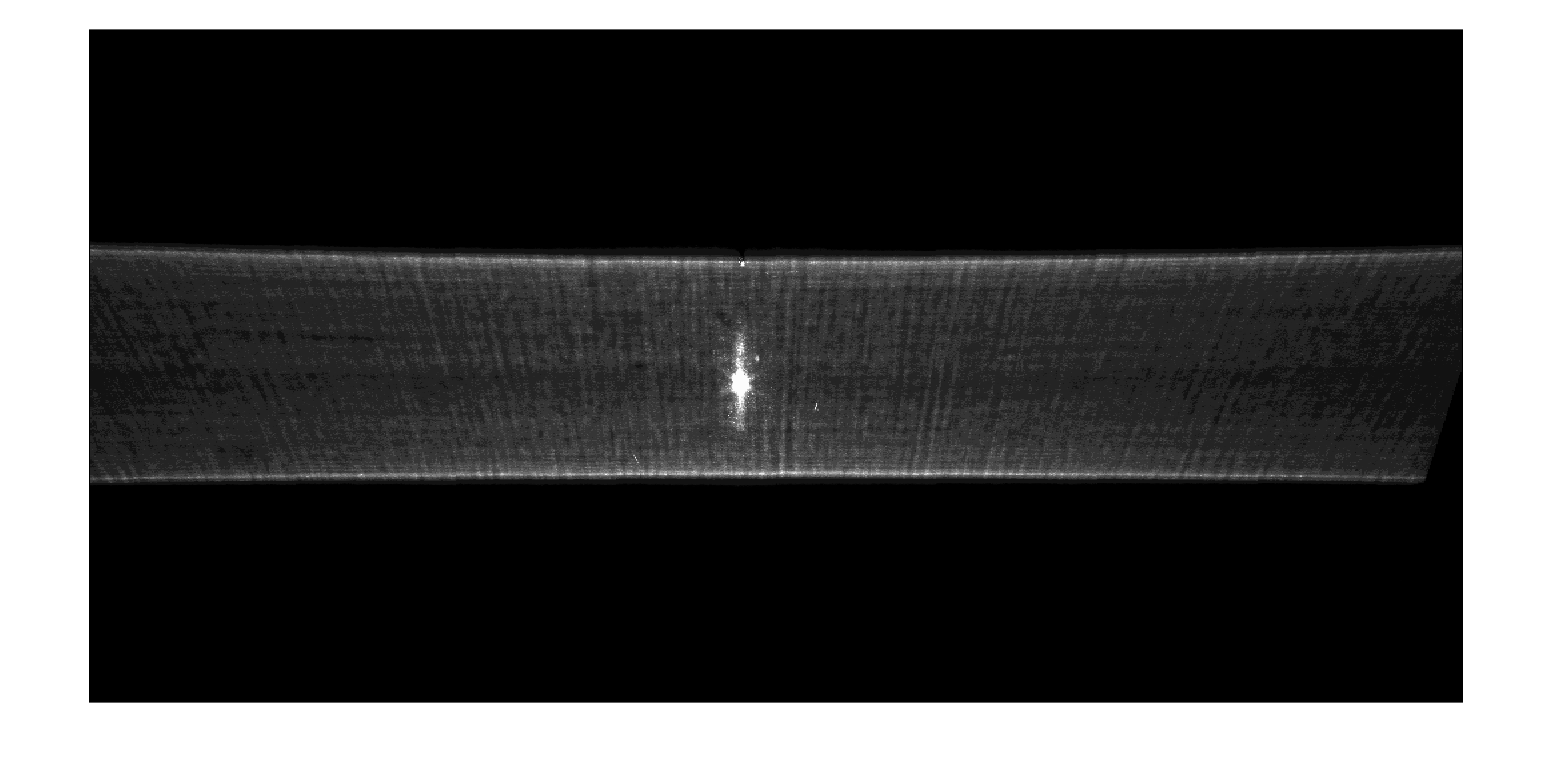

img_folder = uigetdir([],'Select images folder');
cd(img_folder);

% Chargement des images du répertoire et moyenne
% cas acquisition OctOs
octos = 1;
img_list = dir([img_folder,'\save*.png']);
if isempty(img_list)
    % cas acquisition via UVPapp
    img_list = dir([img_folder,'\livecamera20*.png']);
    txt_list = dir([img_folder,'\livecamera20*.txt']);
    octos = 0;
end

% Moyenne des images
img = (imread(img_list(1).name))/numel(img_list);
for i = 2:numel(img_list)
    img = img + (imread(img_list(i).name))/numel(img_list);
end

% Metadata acquisition images (Livecamera)
if octos == 0
    [Shutter, Black_level, Gain, Transferfunc, Lightcorrection,Temperature] = Uvp6ReadMetaFromLivecamera(fullfile(img_folder,"\",char(txt_list(numel(txt_list)).name)));
end

% Figure
fig1 = figure('name','Raw image','Position',[50 50 600 600]);

% Measure intensity profiles and limits to adjust angle
limits = [];
Intensity = [];
img_crop_mean_norm = [];
for i = 1 : 18
    % i=1 and i=2 for extrem part of the light beam
    % NEW : i=3:18 for completing the intensity measurement
    if i == 1
        img_crop = img(100:200,700:end-700);
    elseif i ==2
        img_crop = img(end-200:end-100,700:end-700);
    else
        img_crop = img(200+100*(i-3):200+100*(i-3)+100,700:end-700);
    end
    img_crop_mean = mean(img_crop);
    % Intensity normalization
    min_plot = min(img_crop_mean);
    max_plot = max(img_crop_mean);
    ratio = (img_crop_mean - min_plot) *(255/max_plot);
    img_crop_mean_norm(i,:) = ratio;
    aa = find(ratio > segmentation);
    limits(i,1) = aa(1);
    limits(i,2) = aa(end);
    Intensity(i,1) = mean(img_crop_mean(aa));
end

% Process angle
shift = (limits(1,2) + limits(1,1))/2 - (limits(2,2) + limits(2,1))/2 ;
dist = (size(img,2)-300);
angle_deg = asind(abs(shift)/dist);

% Angle warning
if abs(angle_deg) > angle_limit
    disp('ANGLE of light beam > 2°, results may be biased')
end

% Correct image for rotation
if shift < 0 ; angle_deg = -1 * angle_deg; end
img_crop = img(:,round(mean(mean(limits,2))) - 500 +700:round(mean(mean(limits,2)))+500 +700);
img_rot = imrotate(img_crop,angle_deg + 90,'loose');
imshow(img_rot);

## Final measurements

thick_left = pixel * (limits(1,2) - limits(1,1));
thick_right = pixel * (limits(2,2) - limits(2,1));

% Intensity measurements
mean_left = Intensity(1);
mean_right = Intensity(2);

## Display Profiles

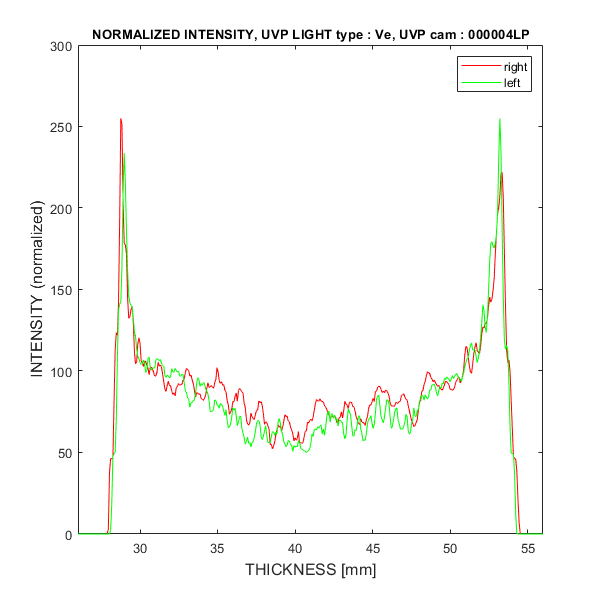

%% vertical profile
fig1 = figure('name','Intensity plots','Position',[50 50 600 600]);
plot([1:size(img_crop_mean_norm,2)]*pixel,img_crop_mean_norm(1,:),'r-')
hold on
plot([1+shift:size(img_crop_mean_norm,2)+shift]*pixel,img_crop_mean_norm(2,:),'g-')
legend('right','left');
titre = ['NORMALIZED INTENSITY, UVP LIGHT type : ',char(uvp_light_type),', UVP cam : ',num2str(uvp_cam)];
title(titre,'fontsize',10);
xlabel('THICKNESS [mm]','fontsize',12);
ylabel('INTENSITY (normalized)','fontsize',12);
axis([ round((limits(1,2) + limits(1,1))/2*pixel) - 15 round((limits(1,2) + limits(1,1))/2*pixel) + 15 0 300])
% ---------------------- Save figure --------------------------------------
orient tall
set(gcf,'PaperPositionMode','auto');
titre = ['NORMALIZED_INTENSITY_type_',char(uvp_light_type),'_camSN_',num2str(uvp_cam)];
print(gcf,'-dpng',['Intensity_plot_',datestr(now,30),'_',char(titre)]);

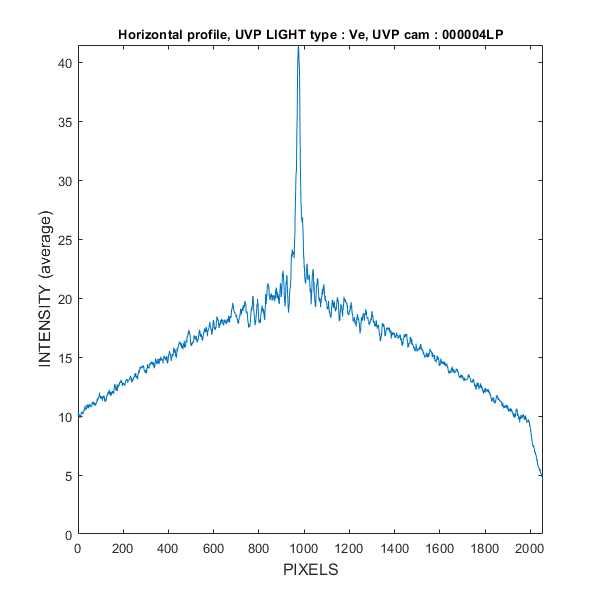


%% horizontal profile
h_profile = mean(img(:,700:end-700), 2);
[max_h_profile, max_h_profile_i] = max(h_profile);
fig1 = figure('name','Intensity plots','Position',[50 50 600 600]);
plot(h_profile)
titre = ['Horizontal profile, UVP LIGHT type : ',char(uvp_light_type),', UVP cam : ',num2str(uvp_cam)];
title(titre,'fontsize',10);
xlabel('PIXELS','fontsize',12);
ylabel('INTENSITY (average)','fontsize',12);
axis([0 2056 0 inf])

## Display results

disp('-------------------------------------------------')

-------------------------------------------------


disp(['Processing date            : ',datestr(now,31)])

Processing date            : 2023-03-28 09:06:23


disp(['Image acquisition date     : ',datestr(img_list(1).datenum,31)])

Image acquisition date     : 2023-03-28 09:03:45


disp(['Number of averaged images  : ',num2str(numel(img_list))])

Number of averaged images  : 18


disp(['Image folder               : ',char(img_folder)])

Image folder               : W:\_UVP6_instruments\Instruments\000004LP\2023\20230328_mesure_intensite_mire_45d_eau


disp(['UVP6 CAMERA s/n            : ',char(uvp_cam)])

UVP6 CAMERA s/n            : 000004LP


disp(['UVP6 LIGHT s/n             : ',char(uvp_light)])

UVP6 LIGHT s/n             : 000004Vep


disp(['UVP6 LIGHT type            : ',char(uvp_light_type)])

UVP6 LIGHT type            : Ve


disp('-------------------------------------------------')

-------------------------------------------------


if octos == 0
    disp('Acquisition parameters (Livecamera)')
    disp(['Shutter                : ',num2str(Shutter)])
    disp(['Black level             : ',num2str(Black_level)])
    disp(['Gain                    : ',num2str(Gain)])
    disp(['Transfer function       : ',num2str(Transferfunc)])
    disp(['Lightcorrection         : ',num2str(Lightcorrection)])    
    disp(['Temperature             : ',num2str(Temperature)])
end

Acquisition parameters (Livecamera)


Shutter                : 50


Black level             : 1


Gain                    : 0


Transfer function       : 3


Lightcorrection         : 0


Temperature             : 22.06


disp('-------------------------------------------------')

-------------------------------------------------


disp(['Position of the beam center [pixel]: ',num2str(max_h_profile_i)])

Position of the beam center [pixel]: 975


disp(['BEAM ANGLE [degre]         : ',num2str(angle_deg)])

BEAM ANGLE [degre]         : 0.23829


disp(['UVP6 pixel [mm]            : ',num2str(pixel)])

UVP6 pixel [mm]            : 0.073


disp(['UVP6 thickness L [mm]      : ',num2str((thick_left),4)])

UVP6 thickness L [mm]      : 25.7


disp(['UVP6 thickness R [mm]      : ',num2str((thick_right),4)])

UVP6 thickness R [mm]      : 25.4


disp(['UVP6 mean thickness [mm] : ',num2str(mean([(thick_right),thick_left]),4)])

UVP6 mean thickness [mm] : 25.55


disp(['UVP6 intensity L           : ',num2str(round(mean_left))])

UVP6 intensity L           : 36


disp(['UVP6 intensity R           : ',num2str(round(mean_right))])

UVP6 intensity R           : 32


disp(['UVP6 intensity MEAN        : ',num2str(mean([(mean_right),mean((mean_left))]),4)])

UVP6 intensity MEAN        : 34.05


disp(['UVP6 intensity MEAN extended : ', num2str(mean(Intensity),4)])

UVP6 intensity MEAN extended : 51.6


disp(['UVP6 estimated image vol[L]: ',num2str(area * mean([(thick_right),thick_left]),2)])

UVP6 estimated image vol[L]: 0.7


disp('-------------------------------------------------')

-------------------------------------------------


disp('REFERENCE THICNESS          : 23 [mm]')

REFERENCE THICNESS          : 23 [mm]


disp('REFERENCE MEAN INTENSITY    : 90')

REFERENCE MEAN INTENSITY    : 90


disp('REFERENCE VOLUME            : 0.63 [L]')

REFERENCE VOLUME            : 0.63 [L]


disp('REFERENCE CENTER            : 1028 [pixel]')

REFERENCE CENTER            : 1028 [pixel]


disp('-------------------------------------------------')

-------------------------------------------------


if strcmp(uvp_light_type, 'Ve')
    disp(['Predicted shutter = ', num2str(shutter_factor), ' x ', num2str(goal_shutter), ' / intensity MEAN'])
    predicted_shutter = shutter_factor * goal_shutter / mean([(mean_right),mean((mean_left))]);
    disp(['shutter x 0.85 : ', num2str(predicted_shutter * 0.85, '%2.0f'), ' µs'])
    disp(['shutter : ', num2str(predicted_shutter, '%2.0f'), ' µs'])
    disp(['shutter x 1.15 : ', num2str(predicted_shutter * 1.15, '%2.0f'), ' µs'])
end

Predicted shutter = 47.6592 x 80 / intensity MEAN


shutter x 0.85 : 95 µs


shutter : 112 µs


shutter x 1.15 : 129 µs


disp('-------------------------------------------------')

-------------------------------------------------
